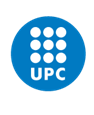

**ESTRUCTURES AEROESPACIALS**

# **The Staircase Project**

*March 2025*

**Authors 1, Author 2**

**[Note: The assignment can be done in groups of two people.]**

## **Introduction**

In the Netflix adaptation of *The Three-Body Problem* book series, the protagonists attempt to send a preserved human brain into space to intercept an incoming alien fleet. Their goal is to accelerate the probe containing the brain to approximately 1% lightspeed ($c=3\times 10^8$ m/s) in order to reach the fleet within a reasonable timeframe. The idea behind the *Staircase Project* is to propel the probe using a series of nuclear explosions to transfer the momentum of the plasma ejected to a solar sail. In this assignment, we will study the feasibility of this project from a structural point of view.

### Estimation of the thrust force

To make an estimation of the thrust force we will make the following assumptions:

- Each detonation ejects $m_p=4.468\times10^6$ kg of plasma (more or less equivalent to a 10-megaton explosion).

- The plasma is released within $t_p=0.1$ seconds in all directions as a sinusoidal pulse (half-period) advancing at a speed of $V_p=125000$ km/s (see Figure 1).

- The plasma pulse reaches the probe at a distance $d=200$ km.

- The total mass of the probe and solar sail is $M=100$ kg, and the pusher plate surface is $S=900$ m${}^2$.

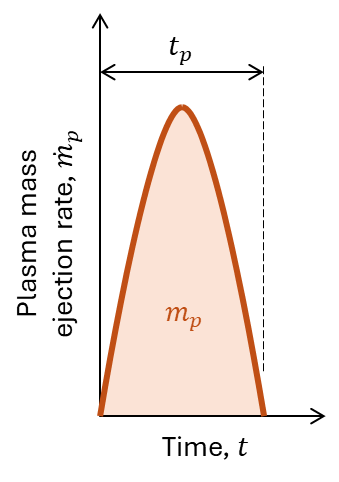

**Figure 1.** Plasma mass ejection rate

    Based on these hypothesis, the mass ejection rate of each nuclear explosion is given by:

 $\dot{m}_p(t)= \frac{\pi}{2} \frac{m_p}{t_p} \sin{\frac{\pi t}{t_p}}$, for $0 \leq t \leq t_p$

Considering $S \ll d^2$ and $V \ll V_p$, from the conservation of linear momentum:


$$M \frac{dV}{dt} \approx \dot{m}_p(t) \frac{S}{4 \pi d^2} V_q$$


Integrating both sides over a period $t_p$ we can obtain the impulse obtained from each nuclear detonation:

$\Delta V \approx \frac{m_p}{M} \frac{S}{4\pi d^2} V_p = 10$ km/s

Acording to these calculations, with 300 concatenated explosions (the number given in the fiction), the probe would reach a velocity close to $V=3000 $ km/s. However, if the detonations are produced at enough distance from one another, the thrust transfered to the structure in each one will be the same. Assuming the force is distributed uniformly over the pusher plate surface, the pressure is given by: 


$$p_\text{T}(t) = \frac{\dot{m}_p(t)}{4 \pi d^2} V_p$$


### Solar sail design

Figure 2 shows a schematic representation of the solar sail. The total mass of the solar sail is $M = $ 100 kg, which includes the mass of the structure (bar elements), $M_\text{S}$. The remaining mass, $M_\text{R} = M - M_\text{S}$, which accounts for the payload, the communications antenna, etc., is distributed: 20% to node 1, 40% to nodes 2, 3, 4 and 5 (10% each), and 40% to node 6.  Reference material properties for each structural component are given in Table 2.

**Table 1.** Material properties.

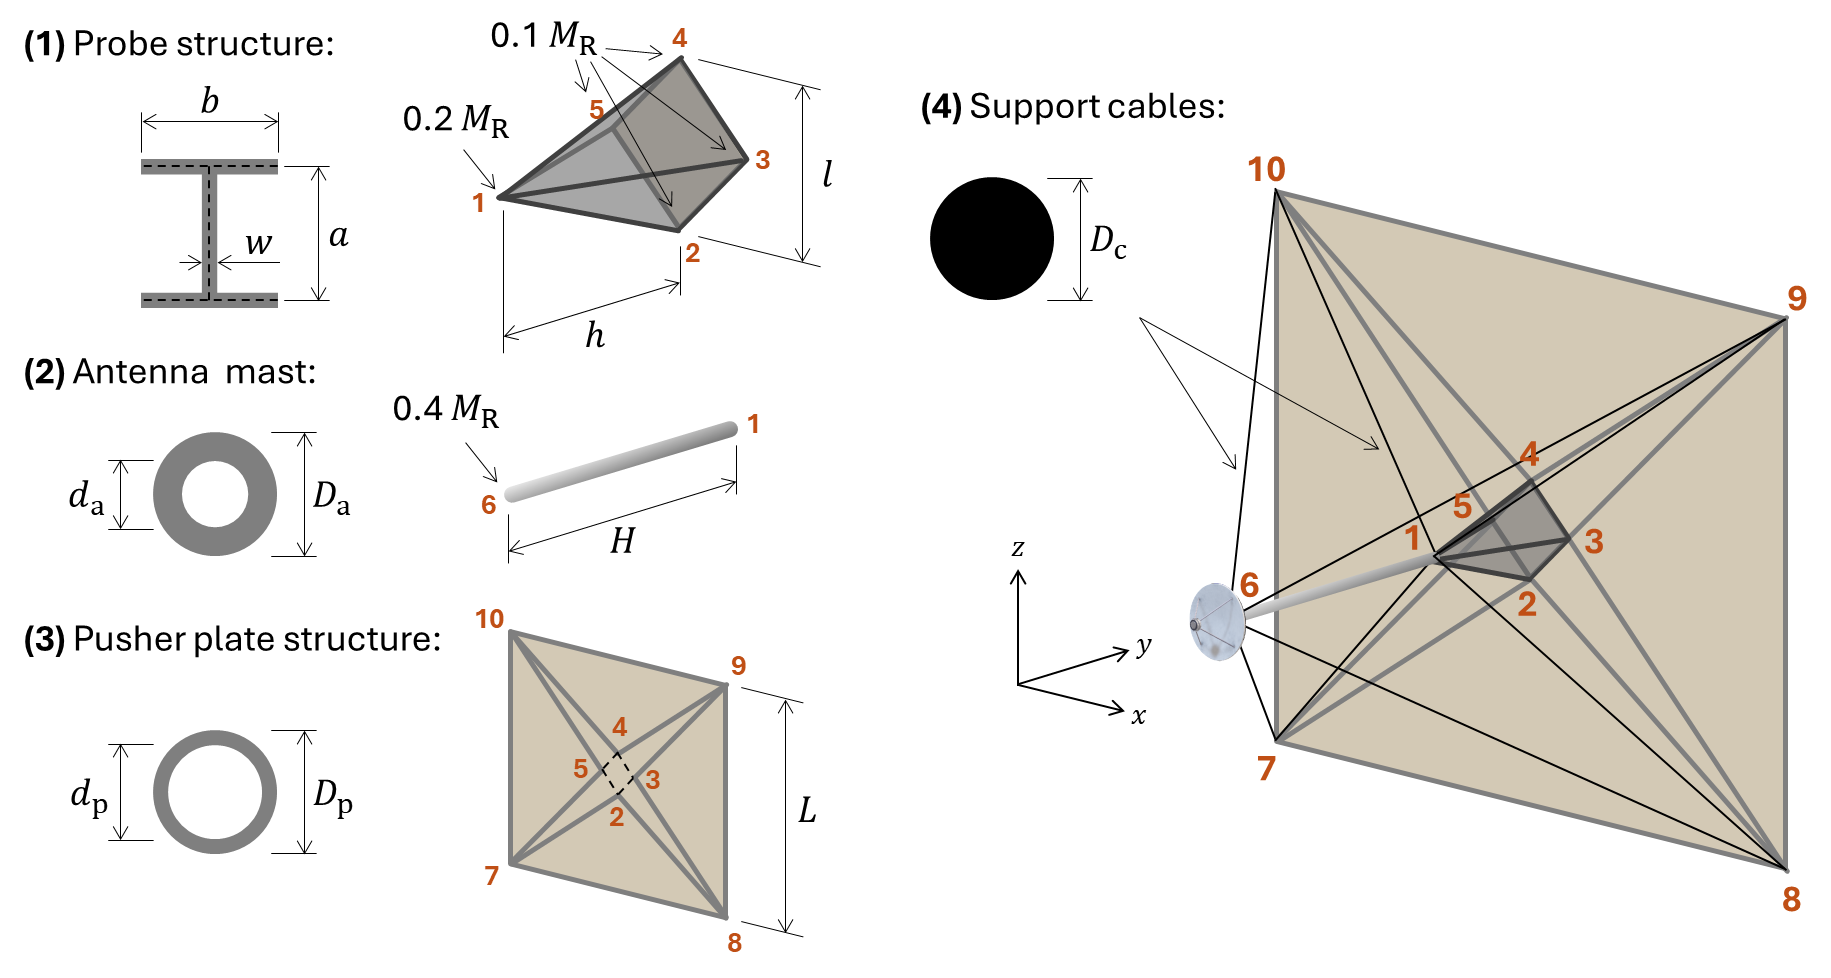

**Figure 1.** Schematic representation of the solar sail structure. Data: $L=$ 30 m, $H=$ 5 m, $l=$ 1 m, $h=$ 1 m, $a=$ 50 mm, $b=$ 25 mm, $w=$ 3 mm, $D_\text{a}=$ 75 mm, $d_\text{a}=$ 50 mm, $D_\text{p}=$ 15 mm, $d_\text{p}=$ 9 mm, $D_\text{c}=$ 5 mm.

Considering that, in each impulse, the thrust force is distributed uniformly over the the pusher plate surface (acting as a time-dependent pressure $p_\text{T}(t)$ defined previously). The following is asked:

- Plot of the deformed structure and stress-state of each element in the most critical scenario. [Optionally, get the results in a sequence of time instants of interest]

- Discuss whether the proposed design is capable of fulfilling the mission according to the hypothesis considered. Are material properties considered realistic? What changes on the solar sail structural design would you suggest to improve the chances of success of the mission? [Example: changing material or geometrical features, adding prestress to elements at risk of buckling, etc.]

Justify your arguments with quantitative metrics.

## Results

[Write here the code to produce the requested results. Comment relevant aspects of the resolution (e.g., what degrees of freedom are prescribed and why?)]

clear % Clear workspace

% Problem data
data.L = 30;
data.H = 5;
data.l = 1;
data.h = 1;

% ...

## Discussion

[Add a discussion of the results and summarize the main conclusions]

## Code functions

Create a function to produce the *mesh* data.

function [xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data,t)

% Nodal coordinates
xnod = [
    0,        0,       0;
    0,        data.h, -data.l/2; 
    data.l/2, data.h,  0;
    0,        data.h,  data.l/2;
   -data.l/2, data.h,  0;
    0,       -data.H,  0;
   -data.L/2, data.h, -data.L/2; 
    data.L/2, data.h, -data.L/2;
    data.L/2, data.h,  data.L/2;
   -data.L/2, data.h,  data.L/2;
];

% Nodal connectivities
Tnod = [
    1 2
    1 3
    1 4
    1 5
    2 3
    3 4
    4 5
    5 2
    1 6
    5 7
    2 7
    2 8
    3 8
    3 9
    4 9
    4 10
    5 10
    7 8
    8 9
    9 10
    10 7
    6 7
    6 8
    6 9
    6 10
    1 7
    1 8
    1 9
    1 10
];

% Material connectivities
Tmat = [
    1 % Probe
    1 
    1 
    1 
    1 
    1 
    1 
    1 
    2 % Antenna mast
    3 % Pusher plate structure
    3
    3
    3
    3
    3
    3
    3
    3
    3
    3
    3
    4 % Support cables
    4
    4
    4
    4
    4
    4
    4
];

% Problem dimensions
data.nnod = size(xnod,1);
data.nd = size(xnod,2);
data.ni = 3;
data.nel = size(Tnod,1);
data.nne = size(Tnod,2);
data.ndof = data.nnod*data.ni;

% ...

end

Create a function to solve the structural problem.

function [disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata)
    
% Write your code here

end

Include any additional function you consider useful to run your code.

function [outputs] = myFunction(intputs)

end

Use the following function to plot the deformed structure. Pay attention to the inputs:

- `disp` is a column vector or a matrix in which each column contains all degrees of freedom (displacements) corresponding to a timestep.

- `stress` is a column vector or a  matrix in which each column contains the stress of each element corresponding to a timestep.

- `scale` is a scaling factor to amplify the displayed deformed (e.g., setting `scale=100` will show the structure 100 times more deformed that the actual deformation values).

- `units` can be used to specify the units in which the stresses are given (e.g., set `units='Pa'` is the values in stress are given in Pa, or `units='MPa'` if they are given in MPa).

Note: If `disp` and `stress` are matrices, the function will produce an animation showing how the structure deforms at each timestep.

function plot3DBars(xnod,Tnod,disp,stress,scale,units)

% Number of steps
N = size(disp,2);

% Precomputations
X = xnod(:,1);
Y = xnod(:,2);
Z = xnod(:,3);
Ux = scale*disp(1:3:end,1);
Uy = scale*disp(2:3:end,1);
Uz = scale*disp(3:3:end,1);
smin = min(stress(:));
smax = max(stress(:));
xmax = max([max(X),max(X+scale*disp(1:3:end,:),[],'all')]);
xmin = min([min(X),min(X+scale*disp(1:3:end,:),[],'all')]);
ymax = max([max(Y),max(Y+scale*disp(2:3:end,:),[],'all')]);
ymin = min([min(Y),min(Y+scale*disp(2:3:end,:),[],'all')]);
zmax = max([max(Z),max(Z+scale*disp(3:3:end,:),[],'all')]);
zmin = min([min(Z),min(Z+scale*disp(3:3:end,:),[],'all')]);

% Open plot window
figure; box on; hold on; axis equal; view(60,15);

% Plot undeformed structure
plot3(X(Tnod'),Y(Tnod'),Z(Tnod'),'-', ...
   'Color',0.85*[1,1,1],'LineWidth',0.5);

% Plot deformed structure with colorbar for stresses 
p = patch(X(Tnod')+Ux(Tnod'),Y(Tnod')+Uy(Tnod'),Z(Tnod')+Uz(Tnod'),[stress(:,1)';stress(:,1)'], ...
    'EdgeColor','interp','LineWidth',1);

% Limits
xlim([xmin,xmax])
ylim([ymin,ymax])
zlim([zmin,zmax])

% Colorbar settings
%clims = get(gca,'clim');
clim(max(abs([smin,smax,1]))*[-1,1]);
n = 128; % Number of rows
c1 = 2/3; % Blue
c2 = 0; % Red
s = 0.85; % Saturation
c = hsv2rgb([c1*ones(1,n),c2*ones(1,n);1:-1/(n-1):0,1/n:1/n:1;s*ones(1,2*n)]');
colormap(c); 
cb = colorbar;

% Add labels
title(sprintf('scale = %g (\\sigma_{min} = %.3g %s | \\sigma_{max} = %.3g %s | step %i)',scale,min(stress(:,1)),units,max(stress(:,1)),units,1)); 
xlabel('x (m)'); 
ylabel('y (m)');
zlabel('z (m)');
cb.Label.String = sprintf('Stress (%s)',units); 

% Plot different timesteps
for i = 1:N
    Ux = scale*disp(1:3:end,i);
    Uy = scale*disp(2:3:end,i);
    Uz = scale*disp(3:3:end,i);
    p.XData = X(Tnod')+Ux(Tnod');
    p.YData = Y(Tnod')+Uy(Tnod');
    p.ZData = Z(Tnod')+Uz(Tnod');
    p.CData = [stress(:,i)';stress(:,i)'];
    title(sprintf('scale = %g (\\sigma_{min} = %.3g %s | \\sigma_{max} = %.3g %s | step %i)',scale,min(stress(:,i)),units,max(stress(:,i)),units,i));
    drawnow
end

end